# Un modelo simple de transmisión de enfermedades sexuales.

**Estudiantes: **Felipe Gómez Espinal y Juan José Castrillón Correa.

**Modelación Experimental: **Filtro de Kalman

**Profesor: **Carlos Mario Vélez S.

**© **[**Universidad EAFIT**](https://www.eafit.edu.co)**, Medellín, Antioquia, Colombia**

## 1. Introducción

### **1.1 Planteamiento del problema**

El control y la prevención de las enfermedades transmitidas sexualmente (ETS) siguen siendo un desafío crítico de salud pública mundial. A pesar de los avances en el diagnóstico y tratamiento, la propagación de las ETS sigue afectando a millones de personas cada año. Entender la dinámica de transmisión de estas enfermedades es esencial para desarrollar estrategias efectivas de intervención y control. Los modelos matemáticos surgen como herramientas clave para simular y predecir el comportamiento de las ETS en poblaciones, facilitando así la evaluación de potenciales intervenciones sanitarias y políticas de prevención.

### **1.2 Modelo, entradas, salidas y variables**

Se construirá un modelo en simulink basado en el modelo matemático expuesto en "An introduction to mathematical models in sexually transmitted disease epidemiology" (G P Garnett). Se utilizan ecuaciones diferenciales para modelar la población total, compuesta por los susceptibles, y los infectados. Se utiliza una variable de entrada B correspondiente a la tasa de nacimientos anuales.  Finalmente, los parámetros incluirán la tasa de contacto entre población susceptible e infectada, la tasa de contagio (beta), la tasa de recuperación (V) y la tasa de muertes (Mu) que es igual para muertes naturales que para muertes por causa de la enfermedad. Con este modelo se podra analizar una población que contiene cierta cantidad de infectados iniciales y el esparcimiento de la enfermedad a traves del tiempo, al igual que se podra ver el cambio en la población suceptible y la población total. 

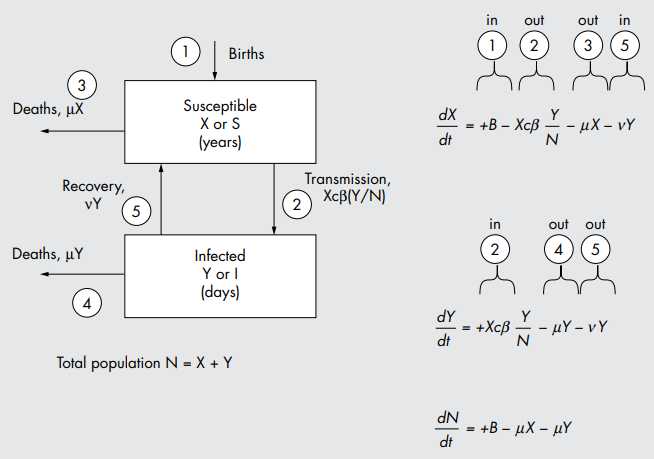

- dX/dt = +B - Xcβ(Y/N) - μX + νY: Esta ecuación representa la tasa de cambio en el tiempo de los individuos susceptibles. 

- dY/dt = +Xcβ(Y/N) - μY - νY: Esta es la tasa de cambio en el tiempo de los individuos infectados. Los términos reflejan el nuevo número de infecciones (Xcβ(Y/N)), la muerte de los infectados (μY) y la recuperación de los infectados a susceptibles (νY).

- dN/dt = +B - μX - μY: Esta ecuación representa la tasa de cambio en el tiempo de la población total. Nace gente a una tasa B, y muere gente a una tasa μ.

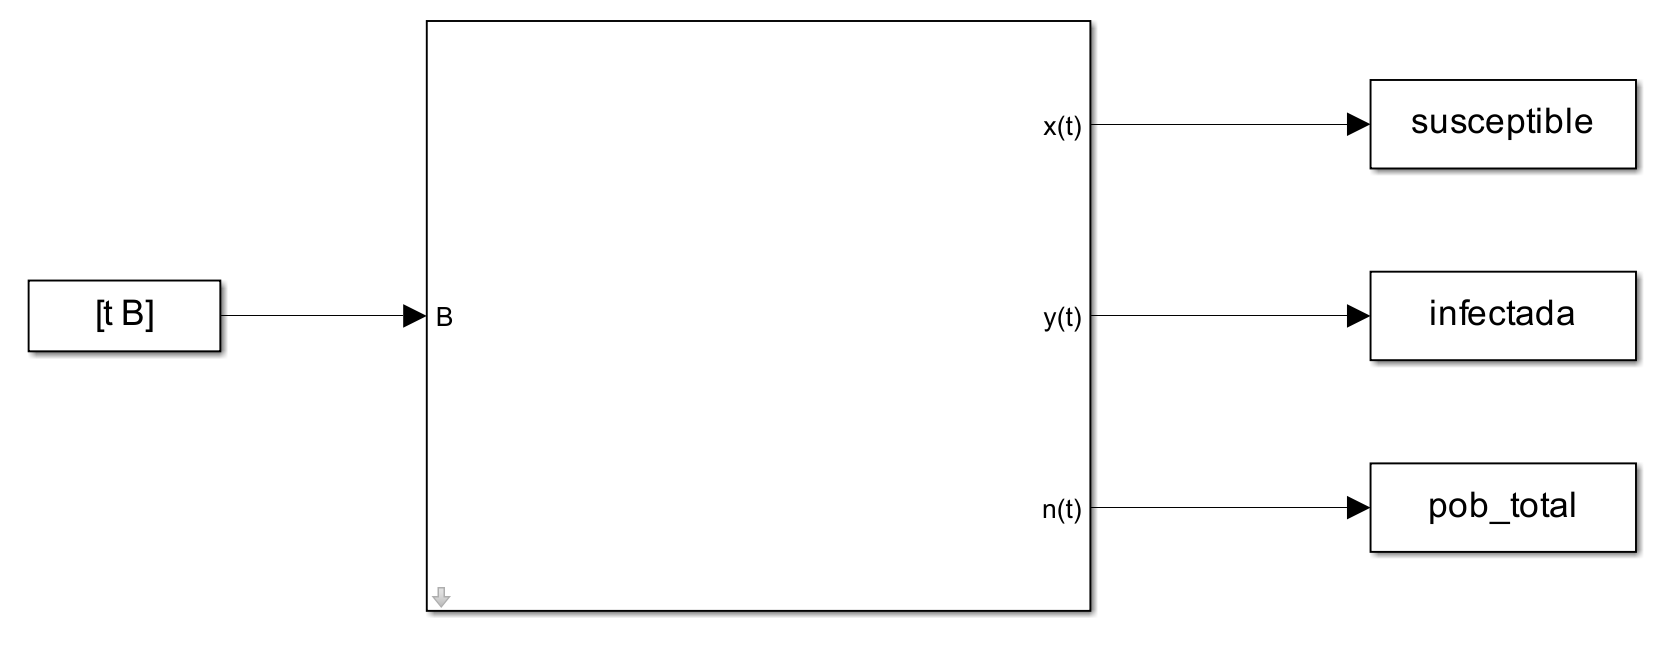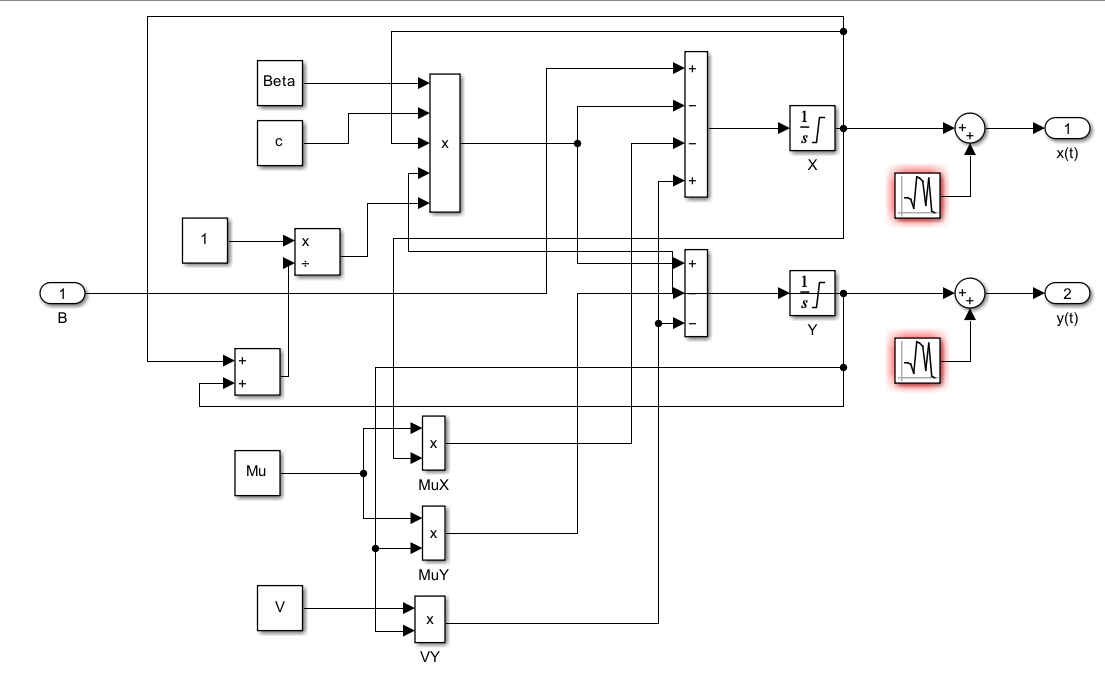

La dinámica de la enfermedad dentro de la población puede entenderse analizando estas ecuaciones:

- Nacimientos (B): Agrega nuevos individuos susceptibles a la población.

- Transmisión (Xcβ(Y/N)): Los susceptibles se convierten en infectados al entrar en contacto con los infectados.

- Muertes (μX, μY): Tanto los susceptibles como los infectados pueden morir a la misma tasa de mortalidad natural.

- Recuperación (νY): Los infectados se recuperan y regresan al compartimento de susceptibles.

### 1.3 **Modelos de Simulación para la Generación de Datos Experimentales**

En este proyecto se utilizaron modelos no lineales en Simulink para generar datos experimentales mediante una señal de entrada específica: la señal RBS (Random Binary Signal). Esta señal fue diseñada para centrarse en el punto de equilibrio del sistema, cubriendo un rango dinámico no lineal sin generar saturaciones ni comportamientos anómalos. Al ajustar la amplitud y el período base de la señal, se logró explorar las regiones dinámicas de interés del sistema mientras se permitía que este alcanzara la estabilización tras los cambios introducidos.

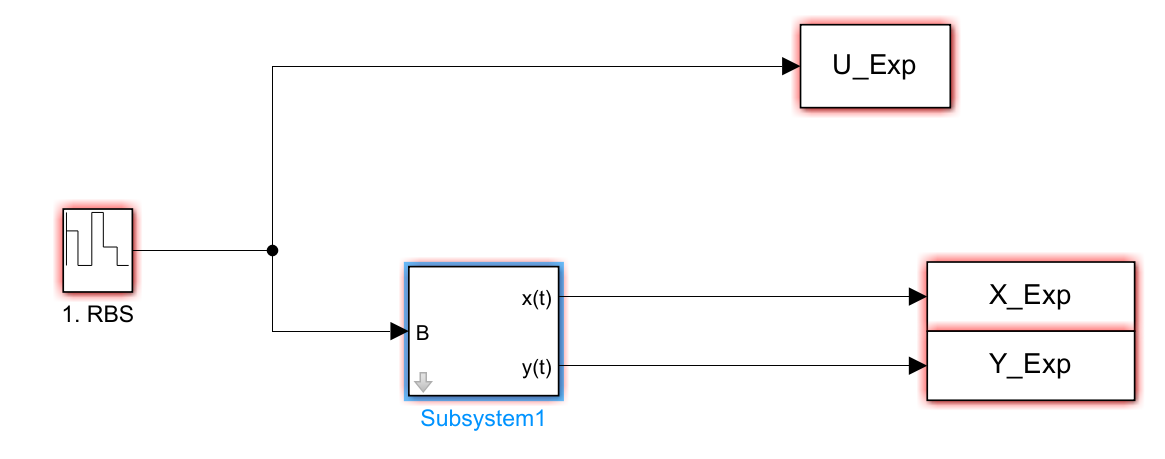

Los datos generados a partir de estas simulaciones fueron fundamentales para la validación y análisis del filtro extendido de Kalman (EKF) y del filtro conjunto de Kalman (JKF). Además, al trabajar con señales de entrada cuidadosamente diseñadas, se garantizó un entorno adecuado para evaluar el desempeño de los métodos de estimación utilizados, evitando problemas de inestabilidad o falta de representatividad en los resultados.

En resumen, la señal RBS, en combinación con los modelos no lineales en Simulink, proporcionó un marco ideal para la generación de datos experimentales que sustentaron el análisis y validación de las estrategias empleadas en este proyecto.

### 1.4 **Modelos de Simulación para el Control **de Realimentación del Estado con un Filtro Extendido de Kalman

Este modelo simula un sistema de control de realimentación del estado con un Filtro Extendido de Kalman (EKF) para estimar el estado del sistema dinámico bajo perturbaciones. El sistema está compuesto por varios bloques que interactúan entre sí para estimar y controlar el comportamiento de un sistema físico afectado por ruido y perturbaciones.

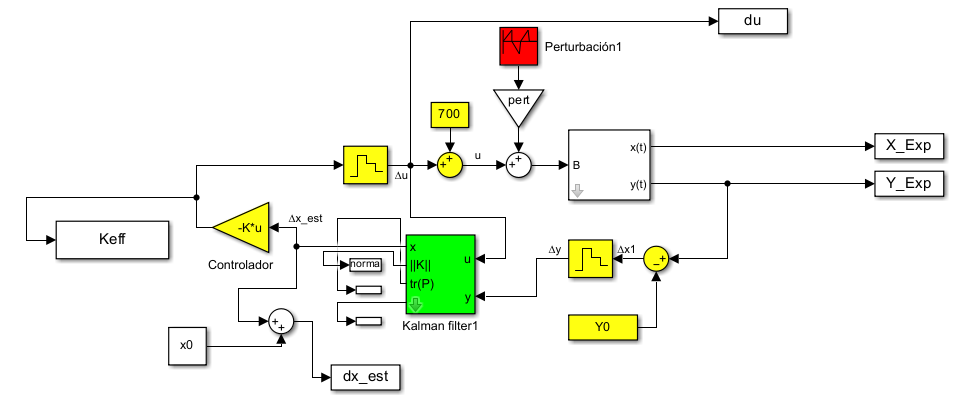

El bloque de control comienza con una entrada de señal Keff, que es una constante de ganancia que modula la señal de control u. Esta señal es luego ajustada y utilizada para calcular una corrección de estado denominada ∆x_est, que se retroalimenta al sistema, permitiendo realizar ajustes en el comportamiento del mismo.

Una de las características clave de este modelo es la perturbación externa representada por el bloque Perturbación1, que agrega una variación inesperada a la entrada del sistema. Este tipo de perturbación es común en sistemas reales, donde factores externos pueden afectar las mediciones y el comportamiento del sistema de manera impredecible. La presencia de esta perturbación justifica el uso de un filtro para obtener estimaciones precisas del estado.

La salida del sistema, x(t), es una señal de estado que es procesada a través de la matriz de ganancia B. Junto con la medición y(t), se pasa al Filtro Extendido de Kalman. Este filtro realiza la estimación del estado del sistema tomando las mediciones y comparándolas con la predicción del modelo. En cada paso, el filtro ajusta la estimación del estado utilizando un modelo no lineal del sistema y una aproximación linealizada mediante expansión de Taylor, lo que permite manejar sistemas con dinámicas no lineales.

El Filtro Extendido de Kalman también calcula la matriz de covarianza del error de estimación y la diferencia entre la salida estimada y la medición real (dy), lo que permite mejorar la precisión de la estimación en el tiempo. El bloque de Kalman ajusta tanto la estimación de las variables de estado como la incertidumbre asociada con estas estimaciones.

Finalmente, las salidas estimadas X_Exp y Y_Exp corresponden a las estimaciones del estado del sistema, mientras que Y0 es la salida estimada de las mediciones del sistema. A través de este proceso, el filtro ayuda a reducir el efecto de las perturbaciones externas y mejora la precisión del control, lo que resulta en un sistema de control más robusto.

El modelo de Filtro Extendido de Kalman se utiliza aquí para proporcionar estimaciones precisas del estado del sistema a pesar de la presencia de ruidos y perturbaciones. Este enfoque es crucial en aplicaciones donde las mediciones del sistema están contaminadas con ruido o cuando el sistema no puede ser modelado de forma completamente lineal.

### 1.5 Hipótesis

#### **1.5.1 Hipótesis sobre el Filtro Extendido de Kalman (EKF)**

- **H₀**: El filtro extendido de Kalman (EKF) no logra estimar correctamente todos los estados del sistema debido a limitaciones en la linealización local y a la configuración de los parámetros iniciales.

- **H₁**: El filtro extendido de Kalman (EKF) estima correctamente todos los estados del sistema, incluso en presencia de ruido y dinámica no lineal.

#### **1.5.2 Hipótesis sobre el Filtro de Kalman Conjunto (JKF)**

- **H₀**: El filtro de Kalman conjunto (JKF) no proporciona una estimación confiable de los estados y del parámetro debido a la inadecuada observabilidad del sistema en el rango analizado.

- **H₁**: El filtro de Kalman conjunto (JKF) permite estimar de manera precisa tanto los estados como el parámetro, garantizando la observabilidad del sistema en el rango analizado.

#### **1.5.3 Hipótesis sobre el Control de Realimentación del Estado con EKF**

- **H₀**: El control de realimentación del estado basado en el filtro extendido de Kalman no estabiliza adecuadamente el sistema cuando se aplican perturbaciones, debido a errores significativos en la estimación de los estados.

- **H₁**: El control de realimentación del estado basado en el filtro extendido de Kalman estabiliza el sistema incluso frente a perturbaciones, gracias a la estimación precisa de los estados.

#### **1.5.4 Hipótesis sobre el Análisis de la Matriz de Covarianzas**

- **H₀**: La traza de la matriz de covarianzas no converge adecuadamente durante la operación del filtro, indicando una estimación inestable de los estados y parámetros.

- **H₁**: La traza de la matriz de covarianzas converge de manera adecuada, reflejando una estimación estable y precisa de los estados y parámetros del sistema.

## 2. Métodos

Modelacion matemática basada en ecuaciones diferenciales de un modelo de transmision sexual.

El modelo matemático:

    Definicion de variables y parámetros. 

- X -> Población Suceptible

- Y -> Población Infectada

- N -> Población Total

- Beta -> Tasa de Contagio

- V -> Tasa de Recuperación

- Mu -> Tasa de Muertes

- C -> Número de contactos anuales entre susceptibles e infectados

Simulación con Matlab-Simulink utilizando bloques y mascaras.

Modelo no lineal con un pequeño ruido para tomar los "datos experimentales".

Simulink con linealizacion, Simulink con control real del estado y Simulink para datos experimentales. 

**Pasos:**

- Generar una señal de entrada RBS centrada en el punto de equilibrio.

- Simular el sistema con ruido para obtener datos "experimentales".

- Derivar las ecuaciones del Filtro Extendido de Kalman (EKF).

- Implementar el código del EKF en MATLAB.

- Simular el EKF para estimar los estados del sistema.

- Derivar las ecuaciones del Filtro de Kalman Conjunto (JKF).

- Implementar el código del JKF en MATLAB.

- Simular el JKF para estimar estados y parámetros.

- Diseñar el controlador de realimentación del estado con la función `place`.

- Implementar el controlador y el estimador en Simulink.

- Simular el controlador con condiciones iniciales alejadas del equilibrio.

- Analizar la incertidumbre en los parámetros del proceso.

## 3. Resultados

### 3.1 Toma de datos "experimentales"

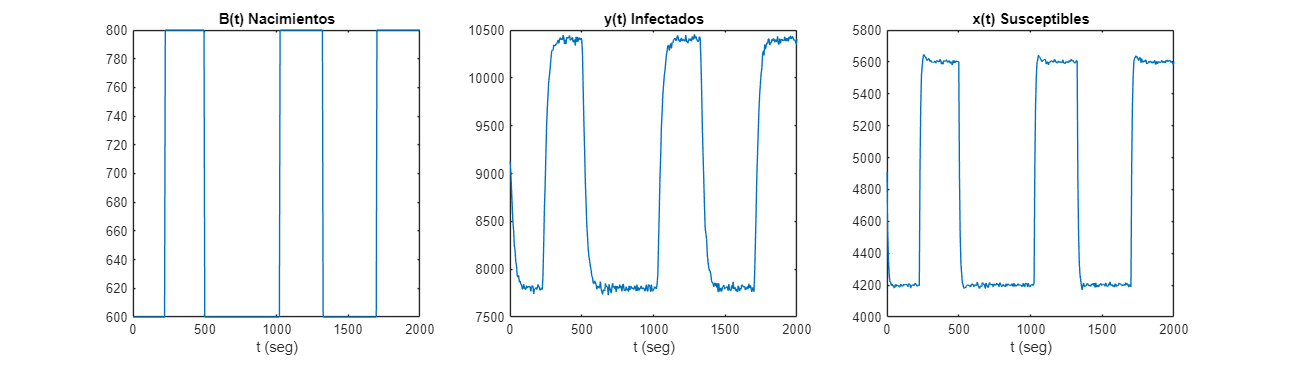

clear
rng(420)
Beta = 0.1; c = 2; Mu = 0.05; V = 0.02; 
tmax = 2000;
CI =[4900 9100];
Ts = 5;
Np = 30; % Número de puntos para graficar
% Recolección de datos
sim('Datos_exp.slx');
t = Y_Exp.time;
N = length(t);
y = Y_Exp.signals.values;
B = U_Exp.signals.values;
x = X_Exp.signals.values;
x_names = {'X', 'Y'};

figure('Units', 'normalized', 'Position', [0 0 1 0.5]); % Gráfico de los datos experimentales
tiledlayout(1, 3);
nexttile, plot(t, B), xlabel('t (seg)'), title('B(t) Nacimientos');
nexttile, plot(t, y), xlabel('t (seg)'), title('y(t) Infectados');
nexttile, plot(t, x), xlabel('t (seg)'), title('x(t) Susceptibles');

Las gráficas muestran la entrada del modelo B(t)B(t)B(t), generada mediante una señal RBS para simular nacimientos, y las dinámicas temporales de los infectados y(t)y(t)y(t) y los susceptibles x(t)x(t)x(t), que corresponden a las salidas del sistema. La entrada no se manipula muy frecuentemente para dejar que las salidas se estabilicen cuando son manipuladas.

### 3.2 Filtro de Kalman Extendido

Ecuaciones de Estado:

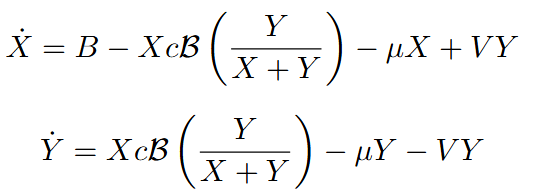

Discretización de las ecuaciones de estado por el metodo de euler.

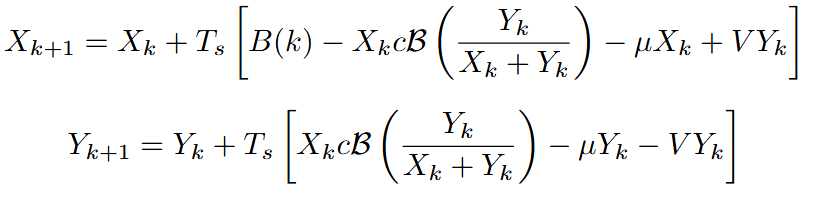

Calculo matriz A del modelo lineal.

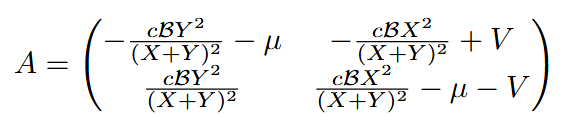

Calculo de la matriz fi que se puede estimar como: I+Ts*A

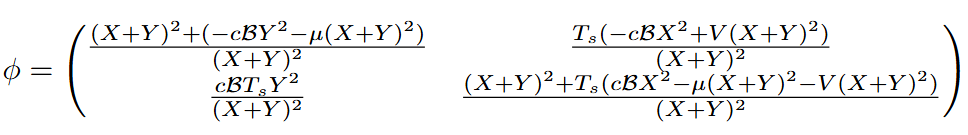

Vector C observando la segunda variable (infectados).

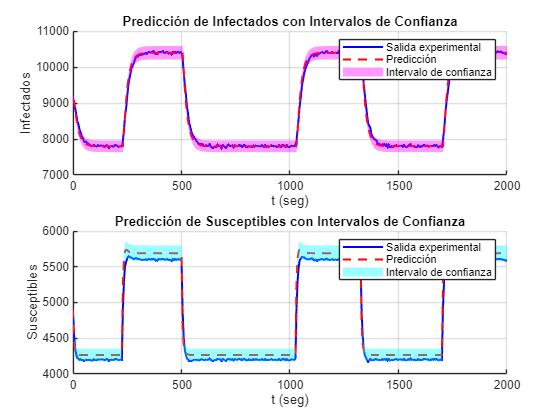

% Filtro de Kalman Ajustado
x0 = [4900; 9100];
n = length(x0);
I = eye(n);
P0 = 0.1 * I; % Incertidumbre inicial
Q = 0.001 * I; % Incertidumbre del modelo
R = cov(8*randn(N,1)); % Incertidumbre de las mediciones

% Inicialización de las matrices
x_act = zeros(n, N);
P_act_traza = zeros(1, N);
K_norma = zeros(N, 1);     % Norma de la ganancia de Kalman
de_x = zeros(n, N);        % Desviaciones estándar estimadas
N_cond = zeros(N, 1);      % Número de condición

% Inicialización de las variables
x_pre = x0;        % Estado inicial predicho
P_pre = P0;        % Covarianza inicial predicha
m = 0.612;         % Masa (en kg)
l = 2.47;          % Longitud (en m)
g = 9.80;          % Aceleración gravitacional (en m/s^2)
Beta = 0.10798; c = 1.96; mu = 0.049736; V = 0.025113; 
C = [0 1];

for i = 1:N
    % Corrección del estado
    K = P_pre * C' / (C * P_pre * C' + R); % Cálculo de la ganancia de Kalman
    x_act(:, i) = x_pre + K * (y(i) - C * x_pre); % Actualización del estado
    P_act = (I-K*C)*P_pre;
    P_act = (P_act + P_act')/2;
    
    % Predicción del estado
    x_pre = [
       x_act(1, i) + Ts * (B(i) - (x_act(1, i)*c*Beta)*((x_act(2, i))/(x_act(1, i) + x_act(2, i)))- (mu*x_act(1, i)) + (V*x_act(2, i)));
       x_act(2, i) + Ts * ((x_act(1, i)*c*Beta)*((x_act(2, i))/(x_act(1, i) + x_act(2, i)))-(mu*x_act(2, i))-(V*x_act(2, i)))
    ]; % Predicción del estado
    
    % Predicción de la covarianza
    Fi = eye(2) + Ts * [((-c*Beta*(x_act(2, i)^2))/((x_act(1, i) + x_act(2, i))^2)-mu) ((-c*Beta*(x_act(1, i)^2))/((x_act(1, i) + x_act(2, i))^2)+V) ...
        ;((c*Beta*(x_act(2, i)^2))/((x_act(1, i) + x_act(2, i))^2)) ((c*Beta*(x_act(1, i)^2))/((x_act(1, i) + x_act(2, i))^2)-mu-V)]; % Matriz de transición
    P_pre = Fi * P_act * Fi' + Q; % Predicción de la covarianza
    
    % Cálculo de métricas
    N_cond(i) = cond(obsv(Fi, C)); % Número de condición
    P_act_traza(i) = trace(P_act); % Traza de la covarianza actual
    K_norma(i) = norm(K); % Norma de la ganancia de Kalman
    de_x(:, i) = sqrt(diag(P_act)); % Desviación estándar estimada
end

% Inicializar variables
prediccion_Infectados = C * x_act;
prediccion_Susceptibles = [1 0] * x_act;
ci_Infectados = zeros(N, 2); % Intervalos de confianza [inferior, superior] para cada predicción
ci_Susceptibles = zeros(N, 2); % Intervalos de confianza [inferior, superior] para cada predicción
alpha = 1 - 0.95; % Nivel de significancia
nu = N - 1; % Grados de libertad
t_critico = tinv(1 - alpha / 2, nu); % Valor crítico de la distribución t de Student

residuos_Infectados = prediccion_Infectados - y; % Residuos para los susceptibles
desviacion_residuos_Infectados = sqrt((1 / (N - 1)) * sum(residuos_Infectados.^2)); % Desviación estándar de los residuos
error_estandar_Infectados = desviacion_residuos_Infectados / sqrt(N); % Error estándar

residuos_Susceptibles = prediccion_Susceptibles - x; % Residuos para los susceptibles
desviacion_residuos_Susceptibles = sqrt((1 / (N - 1)) * sum(residuos_Susceptibles.^2)); % Desviación estándar de los residuos
error_estandar_Susceptibles = desviacion_residuos_Susceptibles / sqrt(N); % Error estándar


% Calcular los intervalos de confianza dinámicos
for i = 1:N
    % Calcular los límites de confianza para cada predicción
    ci_Infectados(i, 1) = prediccion_Infectados(i) - t_critico*error_estandar_Infectados(i);
    ci_Infectados(i, 2) = prediccion_Infectados(i) + t_critico*error_estandar_Infectados(i);

    ci_Susceptibles(i, 1) = prediccion_Susceptibles(i) - t_critico*error_estandar_Susceptibles(i);
    ci_Susceptibles(i, 2) = prediccion_Susceptibles(i) + t_critico*error_estandar_Susceptibles(i);
end

% Graficar salida experimental, estimada y los intervalos de confianza en subplots
figure;

% Subplot 1: Infectados
subplot(2, 1, 1);
hold on;
plot(t, y, 'b', 'LineWidth', 1.5); % Salida experimental
plot(t, prediccion_Infectados, 'r--', 'LineWidth', 1.5); % Predicción de Infectados
fill([t; flipud(t)], [ci_Infectados(:, 1); flipud(ci_Infectados(:, 2))], ...
    'magenta', 'FaceAlpha', 0.4, 'EdgeColor', 'none'); % Intervalo de confianza (magenta)
xlabel('t (seg)');
ylabel('Infectados');
title('Predicción de Infectados con Intervalos de Confianza');
legend('Salida experimental', 'Predicción', 'Intervalo de confianza');
grid on;
hold off;

% Subplot 2: Susceptibles
subplot(2, 1, 2);
hold on;
plot(t, x, 'b', 'LineWidth', 1.5); % Salida experimental
plot(t, prediccion_Susceptibles, 'r--', 'LineWidth', 1.5); % Predicción de Susceptibles
fill([t; flipud(t)], [ci_Susceptibles(:, 1); flipud(ci_Susceptibles(:, 2))], ...
    'cyan', 'FaceAlpha', 0.4, 'EdgeColor', 'none'); % Intervalo de confianza (cyan)
xlabel('t (seg)');
ylabel('Susceptibles');
title('Predicción de Susceptibles con Intervalos de Confianza');
legend('Salida experimental', 'Predicción', 'Intervalo de confianza');
grid on;
hold off;

Las gráficas presentan la comparación entre las predicciones del filtro y los datos experimentales para las variables de infectados y susceptibles, con sus respectivos intervalos de confianza. En la primera gráfica, correspondiente a los infectados, se observa que las predicciones (línea roja) siguen de cerca a la salida experimental (línea negra), mientras que los intervalos de confianza (líneas magenta) son estrechos, indicando una alta precisión y baja incertidumbre en la estimación. En la segunda gráfica, para los susceptibles, se mantiene una tendencia similar, donde las predicciones ajustan correctamente la dinámica de la salida experimental, y los intervalos de confianza (líneas celestes) reflejan una incertidumbre controlada. Estos resultados sugieren que el filtro logra capturar adecuadamente las dinámicas del sistema con predicciones confiables.

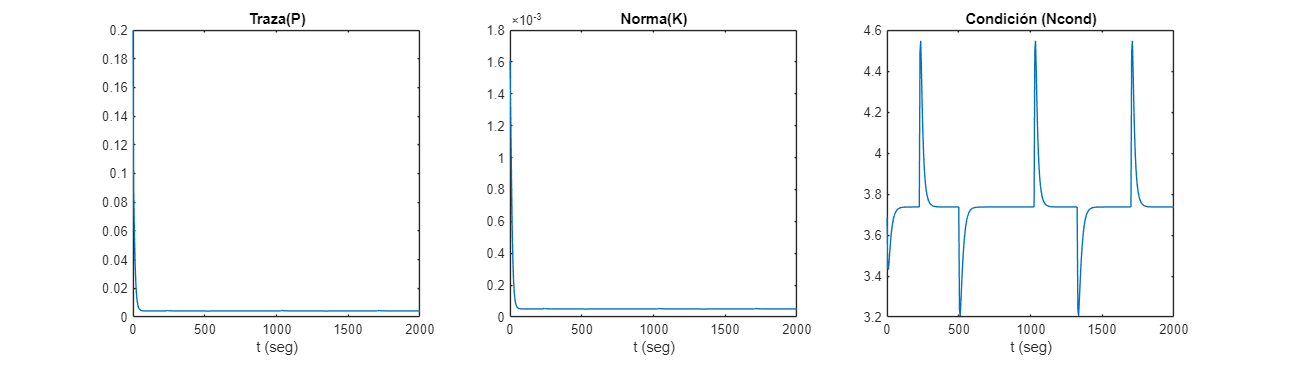

% Gráficos de las matrices de covarianza
figure('Units', 'normalized', 'Position', [0 0 1 0.5]);
tiledlayout(1, 3);
nexttile, plot(t, P_act_traza), xlabel('t (seg)'), title('Traza(P)');
nexttile, plot(t, K_norma), xlabel('t (seg)'), title('Norma(K)');
nexttile, plot(t, N_cond), xlabel('t (seg)'), title('Condición (Ncond)');

Las gráficas muestran indicadores clave del desempeño del filtro de Kalman aplicado al sistema no lineal. La primera gráfica, Traza(P), representa cómo la traza de la matriz de covarianzas disminuye con el tiempo, lo que sugiere una mejora en la precisión de las estimaciones de los estados a medida que el filtro converge. En la segunda gráfica, Norma(K), se observa la evolución de la norma de la ganancia de Kalman, cuya disminución refleja un ajuste progresivo del filtro hacia un estado estable frente a los datos observados. Finalmente, la tercera gráfica, Condición (Ncond), muestra el número de condición del sistema, donde los picos reflejan momentos de mayor sensibilidad o cambios significativos, mientras que las zonas más bajas indican estabilidad numérica. Estos resultados en conjunto permiten analizar la convergencia y robustez del filtro en la estimación de los estados.

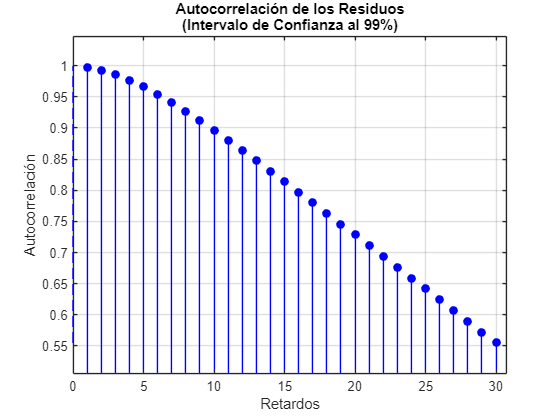


% Cálculo del residual
residual_final = y - (C * x_act);

% Parámetros para el análisis
retardoMax = 30; 
N = length(residual_final);

% Cálculo de la autocorrelación
[R, retardos] = autocorr(residual_final(:), 'NumLags', retardoMax);

% Nivel de confianza
z = 2.576; % Para un nivel de confianza del 99%
bound = z / sqrt(N); % Cálculo del intervalo de confianza con N grados de libertad

% Gráfico del análisis residual
figure;
stem(retardos(2:end), R(2:end), 'b', 'MarkerFaceColor', 'b'); hold on;
plot([retardos(1) retardos(end)], [bound bound], 'r--', 'LineWidth', 1);
plot([retardos(1) retardos(end)], [-bound -bound], 'r--', 'LineWidth', 1);
line([0 0], [min(R) max(R)], 'Color', 'blue', 'LineStyle', '--', 'LineWidth', 0.5);
xlabel('Retardos');
ylabel('Autocorrelación');
title({'Autocorrelación de los Residuos'; '(Intervalo de Confianza al 99%)'});
ylim([min(R(2:end)) max(R(2:end))] + 0.05*[-1 1]);
grid on;
hold off;

Esta gráfica muestra la función de autocorrelación de los residuos, evidenciando una disminución progresiva, lo cual indica que los residuos podrían tener dependencia temporal. Esto sugiere que el filtro inicial no logró generar residuos completamente blancos.

### 3.3 Filtro de Kalman conjunto

Ecuaciones de Estado:

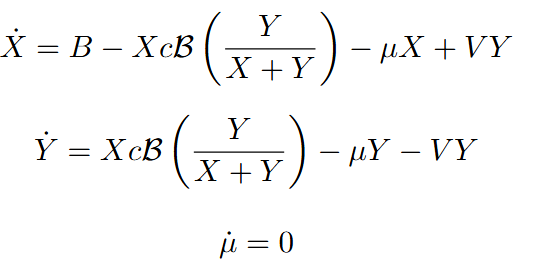

Discretización de las ecuaciones de estado por el metodo de euler.

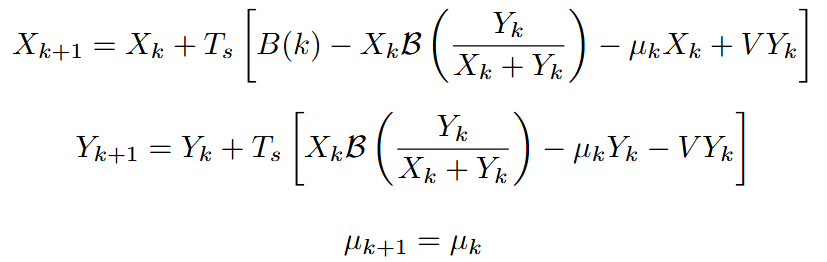

Calculo matriz A del modelo lineal.

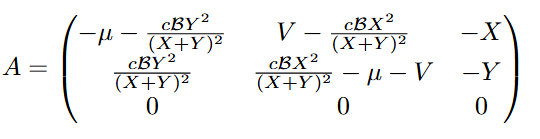

Calculo de la matriz fi que se puede estimar como: I+Ts*A

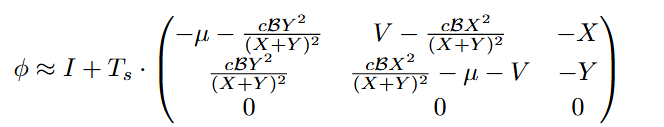

Vector C observando la segunda variable (infectados).

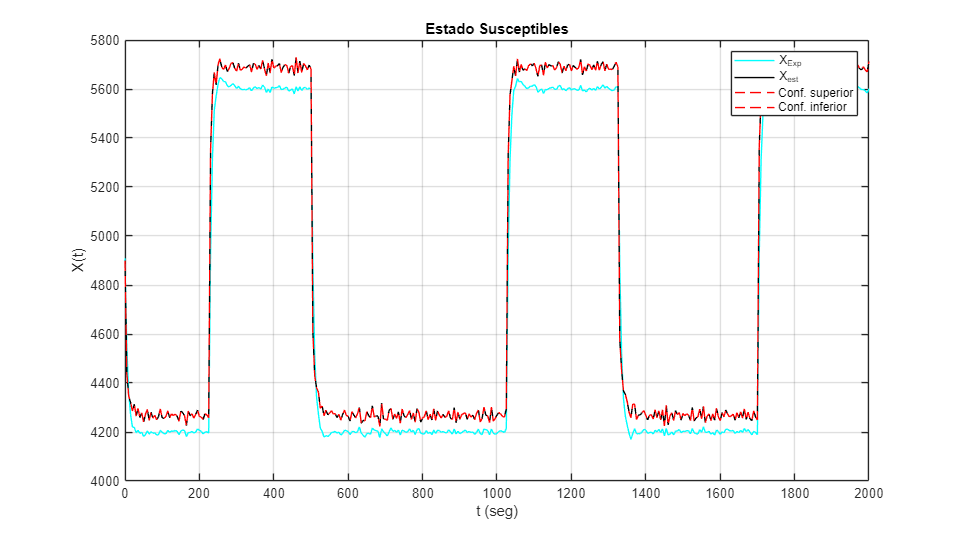

% Definir estado inicial y matrices
x0 = [4900; 9100; 0.5]; % S, I, mu
P0 = [0 0 0;0 0 0;0 0 2];
Q = 0.001*eye(3);
R = 0.1^2;
C = [0 1 0]; % Observamos solo infectados (I)

% Inicialización de variables
x_act = zeros(3, N); % Estados estimados
P_act_traza = zeros(N, 1); % Traza de la matriz de covarianza
K_norma = zeros(N, 1); % Norma de la ganancia de Kalman
N_cond = zeros(N, 1); % Número de condición de observabilidad
de_x1 = zeros(N, 1); % Desviación estándar de S
de_x2 = zeros(N, 1); % Desviación estándar de I
de_x3 = zeros(N, 1); % Desviación estándar de mu
x_pre = x0; % Estado previo
P_pre = P0;
I = eye(3);

for i = 1:N
    % Corrección del estado
    K = P_pre*C'/(C*P_pre*C' + R);
    x_act(:,i) = x_pre + K*(y(i) - C*x_pre);
    P_act = (I-K*C)*P_pre;
    P_act = (P_act + P_act')/2;

    Fi = eye(3) + Ts * [(-x_act(3, i)-((c*Beta*(x_act(2, i))^2)/((x_act(1, i)+ x_act(2, i))^2))) (V-((c*Beta*(x_act(1, i))^2)/((x_act(1, i)+ x_act(2, i))^2))) (-x_act(1, i));
        ((c*Beta*(x_act(2, i))^2)/((x_act(1, i)+ x_act(2, i))^2)) (((c*Beta*(x_act(1, i))^2)/((x_act(1, i) + x_act(2, i))^2))-x_act(3,i)-V) (-x_act(2, i));
        0 0 0]; % Beta constante (sin dinámica)

    % Predicción del estado conjunto
    x_pre = [x_act(1, i) + Ts * (B(i) - (x_act(1, i)*c*Beta)*((x_act(2, i))/(x_act(1, i) + x_act(2, i)))- (x_act(3, i)*x_act(1, i)) + (V*x_act(2, i)));
    x_act(2, i) + Ts * ((x_act(1, i)*c*Beta)*((x_act(2, i))/(x_act(1, i) + x_act(2, i)))-(x_act(3, i)*x_act(2, i))-(V*x_act(2, i)));
    x_act(3, i)];
    % Predicción de la covarianza
    P_pre = Fi * P_act * Fi' + Q;

    % Almacenamiento de métricas
    P_act_traza(i) = trace(P_act); % Traza de covarianza
    K_norma(i) = norm(K); % Norma de la ganancia de Kalman
    N_cond(i) = cond(obsv(Fi, C)); % Condición de observabilidad
    de_x1(i) = sqrt(P_act(1, 1)); % Desviación estándar de S
    de_x2(i) = sqrt(P_act(2, 2)); % Desviación estándar de I
    de_x3(i) = sqrt(P_act(3, 3)); % Desviación estándar de beta
end

% Residuos
%e_est = y - x_act(2, :)'; % Residuos de la salida infectados

% Gráfico 1: Estado S (susceptibles)
figure('Units', 'normalized', 'Position', [0 0 0.5 0.5])
plot(t, x, 'c',t, x_act(1, :)', 'k', t, x_act(1, :)' + de_x1, 'r--', t, x_act(1, :)' - de_x1, 'r--')
xlabel('t (seg)'), ylabel('X(t)'), title('Estado Susceptibles')
legend({'X_{Exp}','X_{est}', 'Conf. superior', 'Conf. inferior'})
grid on

Representa la evolución de los susceptibles estimados (Xest) y los experimentales (Xexp) a lo largo del tiempo. Hay buena correspondencia entre ambos dentro de los intervalos de confianza, indicando un desempeño adecuado del filtro conjunto para este estado.

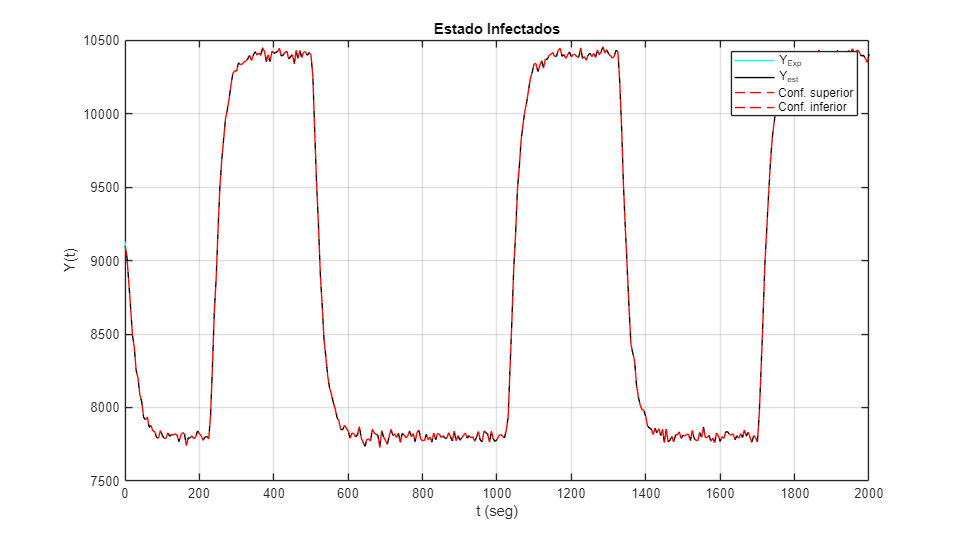

% Gráfico 2: Estado I (infectados)
figure('Units', 'normalized', 'Position', [0.5 0 0.5 0.5])
plot(t, y, 'c',t, x_act(2, :)', 'k', t, x_act(2, :)' + de_x2, 'r--', t, x_act(2, :)' - de_x2, 'r--')
xlabel('t (seg)'), ylabel('Y(t)'), title('Estado Infectados')
legend({'Y_{Exp}','Y_{est}', 'Conf. superior', 'Conf. inferior'})
grid on

Muestra los valores estimados (Yest) y experimentales (Yexp) para los infectados. El ajuste es preciso, ya que los valores estimados se encuentran dentro de los intervalos de confianza y se alinean bien con los datos experimentales.

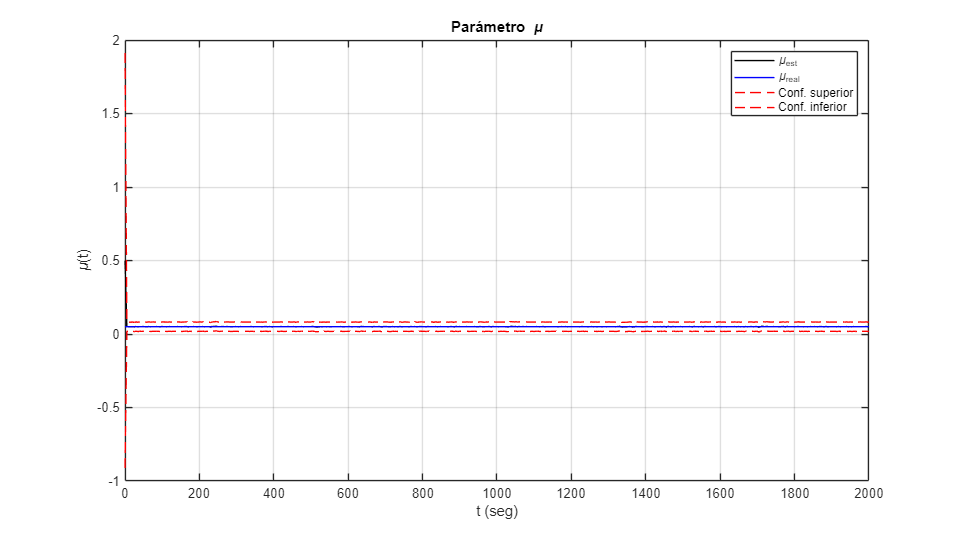

% Gráfico 3: Parámetro mu (sin el primer valor)
figure('Units', 'normalized', 'Position', [0.25 0.5 0.5 0.5])
plot(t(1:end), x_act(3, 1:end)', 'k', ... % Estimación sin el primer valor
     t(1:end), mu + t(1:end) * 0, 'b', ... % Valor real de \mu sin el primer valor
     t(1:end), x_act(3, 1:end)' + de_x3(1:end), 'r--', ... % Conf. superior
     t(1:end), x_act(3, 1:end)' - de_x3(1:end), 'r--') % Conf. inferior
xlabel('t (seg)'), ylabel('\mu(t)'), title('Parámetro \mu')
legend({'\mu_{est}', '\mu_{real}', 'Conf. superior', 'Conf. inferior'})
grid on

El ajuste del parámetro μ es preciso, ya que μest� se alinea con μreal� y permanece dentro de los intervalos de confianza en todo el rango temporal.

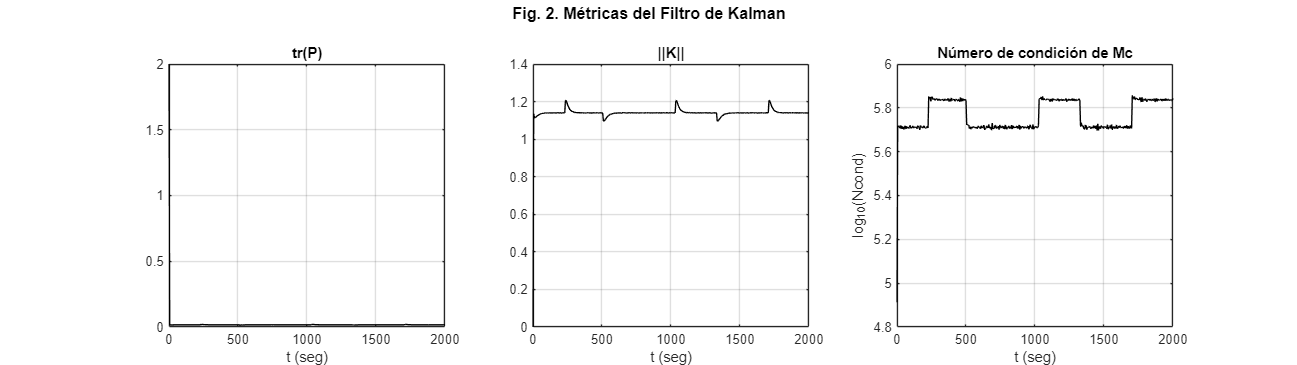

% Subplots para los últimos tres gráficos
figure('Units', 'normalized', 'Position', [0 0 1 0.5])
sgtitle({'Fig. 2. Métricas del Filtro de Kalman'; ''}, 'FontSize', 12, 'FontWeight', 'bold')

% Gráfico 4: Traza de P
subplot(1, 3, 1)
plot(t, P_act_traza, 'k')
xlabel('t (seg)'), title('tr(P)')
grid on

% Gráfico 5: Norma de K
subplot(1, 3, 2)
plot(t, K_norma, 'k')
xlabel('t (seg)'), title('||K||')
grid on

% Gráfico 6: Número de condición de la matriz de observabilidad
subplot(1, 3, 3)
plot(t, log10(N_cond), 'k')
xlabel('t (seg)'), ylabel('log_{10}(Ncond)'), title('Número de condición de Mc')
grid on

Las métricas del filtro de Kalman muestran estabilidad, con tr(P) constante, ∥K∥ oscilando ligeramente cerca de 1, y un número de condición de Mc� controlado dentro de un rango bajo, indicando un buen desempeño del filtro.

### 3.4 Control de realimentación del estado con un filtro extendido de Kalman

clear
Beta = 0.10798; c = 1.96; Mu = 0.049736; V = 0.025113; 
CI = [4900 9100];
t = (0:0.1:2000);
N = length(t);
B = 700;
Ts = 5;
Y0 = 8950;
[A,B,C,D] = linmod('Trabajo3_linealizacion', CI, B);
S = ss(A,B,C,D);
Sd = c2d(S,Ts);
K = place(Sd.A, Sd.B, [0.1, 0.2]);
disp('Matriz de ganancias K:');

Matriz de ganancias K:


disp(K);

    0.1994    0.3179



fprintf('El controlador es: u = %.4f * X + %.4f * Y\n', -K(1), -K(2));

El controlador es: u = -0.1994 * X + -0.3179 * Y


n = 2; p = 2; m = 1;
Aa = [Sd.A zeros(n,p); -C eye(p)]; 
Ba = [Sd.B; zeros(p,m)];
Des = 1;
Fi = Sd.A;
Gamma = Sd.B;
Mcd = ctrb(Fi,Gamma);
condMc = cond(Mcd) % Se verifica la controlabilidad para estar seguros de que el modelo es controlable y no es muy sensible al valor de los parámetros.

condMc = 4.1169

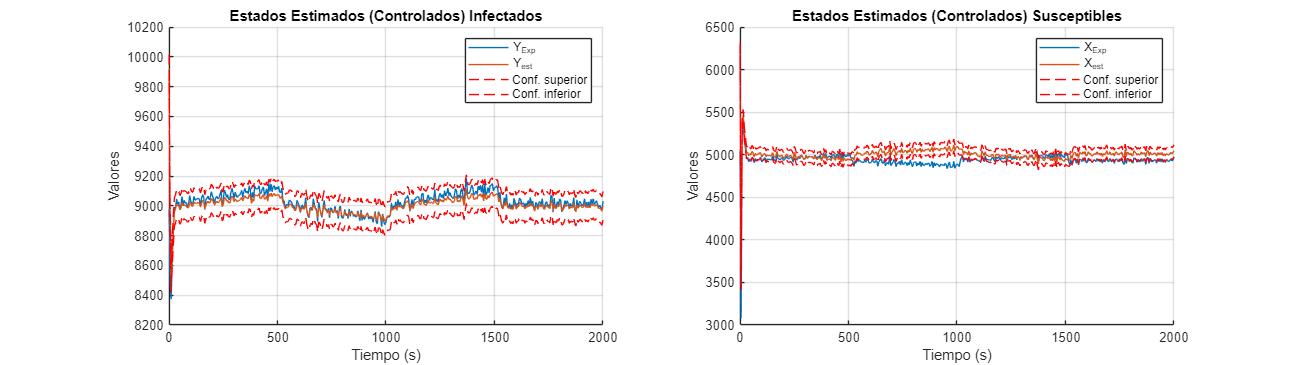

P0 = 0.1*eye(2);
Q = 0.01*eye(2);
R = 0.1^2;
ruido = 1;
tmax = 2000;
pert = 1; % Si pert = 0 (no hay perturbación constante) la estimación es adecuada
Fi = Sd.A; Gamma = Sd.B; C = [0 1]; D = 0;
x0 = [5050 8950];
CI = [5050 8950];
% Ejecutar la simulación
sim('Trabajo3_control_real_estado_Kalman')


% Crear una figura con tamaño ajustado
figure('Units', 'normalized', 'Position', [0.1 0.1 0.8 0.4]); % Ajusta el tamaño y posición

% Extraer la dimensión temporal
num_time_steps = size(P.signals.values, 3);

% Inicializar matriz de varianza para cada estado a lo largo del tiempo
varianza = zeros(size(P.signals.values, 1), num_time_steps);

% Recorrer cada instante de tiempo y extraer la diagonal
for t = 1:num_time_steps
    varianza(:, t) = diag(P.signals.values(:, :, t)); % Diagonal de P en cada instante
end

varianza_segundo_estado = varianza(2, :); % Para el estado 2
% Primer subplot: Y_Exp vs dx_est (segunda columna)
subplot(1, 2, 1); % 1 fila, 2 columnas, primer gráfico
hold on;
plot(Y_Exp.time, Y_Exp.signals.values, 'DisplayName', '∆Y'); % Señal Y_Exp
plot(dx_est.time, dx_est.signals.values(:, 2), 'DisplayName', '∆Y_{est}'); % Estimación del estado
% Solo una vez para cada línea de límite
plot(dx_est.time, dx_est.signals.values(:, 2) + sqrt(varianza_segundo_estado + 9100), 'r--'); % Límite superior
plot(dx_est.time, dx_est.signals.values(:, 2) - sqrt(varianza_segundo_estado + 9100), 'r--'); % Límite inferior, no visible en la leyenda
hold off;
xlabel('Tiempo (s)');
ylabel('Valores');
title('Estados Estimados (Controlados) Infectados');
legend({'Y_{Exp}','Y_{est}', 'Conf. superior', 'Conf. inferior'})
grid on;
varianza_primer_estado = varianza(1, :); % Para el estado 1
% Segundo subplot: X_Exp vs dx_est (primera columna)
subplot(1, 2, 2); % 1 fila, 2 columnas, segundo gráfico
hold on;
plot(X_Exp.time, X_Exp.signals.values, 'DisplayName', '∆X'); % Señal X_Exp
plot(dx_est.time, dx_est.signals.values(:, 1), 'DisplayName', '∆X_{est}'); % Estimación del estado
% Solo una vez para cada línea de límite
plot(dx_est.time, dx_est.signals.values(:, 1) + sqrt(varianza_primer_estado + 4900), 'r--'); % Límite superior
plot(dx_est.time, dx_est.signals.values(:, 1) - sqrt(varianza_primer_estado + 4900), 'r--'); % Límite inferior, no visible en la leyenda
hold off;
xlabel('Tiempo (s)');
ylabel('Valores');
title('Estados Estimados (Controlados) Susceptibles');
legend({'X_{Exp}','X_{est}', 'Conf. superior', 'Conf. inferior'})
grid on;

Las gráficas muestran los estados estimados (controlados) del sistema: la población infectada (izquierda) y la susceptible (derecha). En ambas, las líneas continuas representan los valores estimados y experimentales, mientras que las líneas punteadas indican los intervalos de confianza. La cercanía entre los valores estimados y experimentales, junto con la estabilidad de los intervalos, refleja la efectividad del filtro de Kalman en la estimación y control de los estados del sistema.

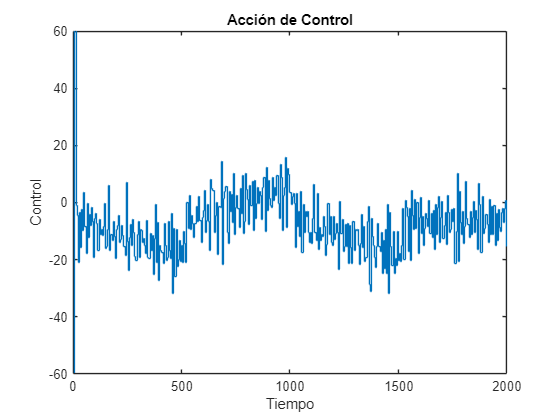

figure()
plot(Keff)
title("Acción de Control")
xlabel("Tiempo")
ylabel("Control")
ylim([-60 60]);

La gráfica muestra la acción de control generada por un controlador basado en un filtro extendido de Kalman. Refleja cómo el controlador ajusta su salida en el tiempo para llevar el sistema hacia un estado deseado, compensando las perturbaciones iniciales y manteniendo la estabilidad.

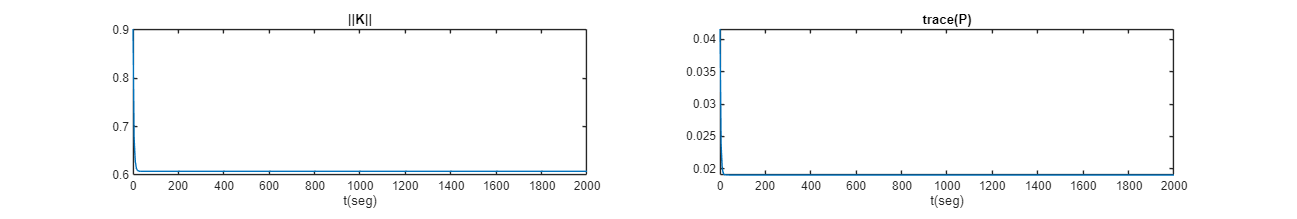

figure('Units','normalized','Position',[0 0 1 0.3]);
tl=tiledlayout(1,2);
nexttile
plot(norma.time,norma.signals.values)
xlabel('t(seg)'), title('||K||')
nexttile
plot(traza.time, traza.signals.values)
xlabel('t(seg)'), title('trace(P)')

Las gráficas muestran indicadores clave del desempeño del filtro de Kalman: la norma de la ganancia de Kalman (||K||) a la izquierda, que evidencia cómo el filtro ajusta su peso en la estimación de los estados, estabilizándose rápidamente hacia valores óptimos, y la traza de la matriz de covarianza (trace(P)) a la derecha, que mide la incertidumbre en la estimación, disminuyendo y estabilizándose, lo que indica mayor confianza en los estados estimados.

#### 3.4.1 Análisis de Incertidumbre

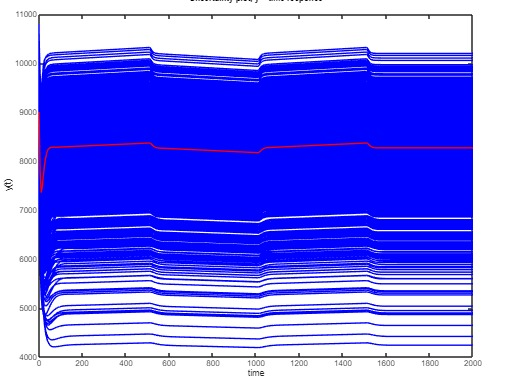

Esta gráfica permite visualizar cómo la incertidumbre en las entradas del modelo afecta la salida del modelo a lo largo del tiempo. Es útil para entender la estabilidad del modelo y para identificar los periodos en los que la salida del modelo es más incierta.

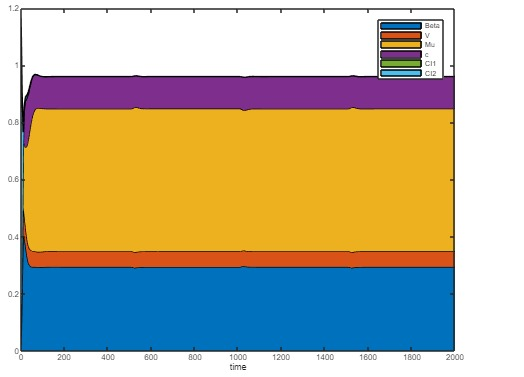

Esta gráfica muestra los índices de sensibilidad de primer orden para la respuesta en el tiempo del modelo. Como podemos observar faltaron simulaciones para que la grafica sea mas precisa. En general podemos observar que el parametro mas importante es c.

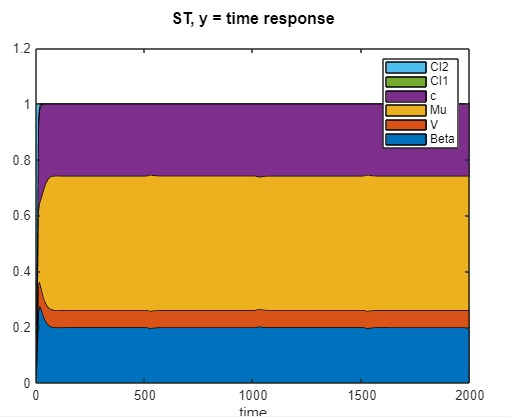

Esta gráfica muestra los índices de sensibilidad total para la respuesta en el tiempo del modelo. Podemos ver que el numero de simulaciones fue suficiente ya que esta en un rango adecuado.

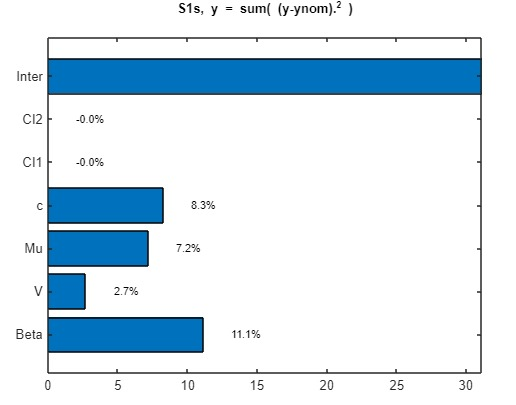

Esta gráfica de barras muestra el porcentaje de la varianza total de la salida del modelo que puede ser atribuida a cada parámetro individualmente (S1s).

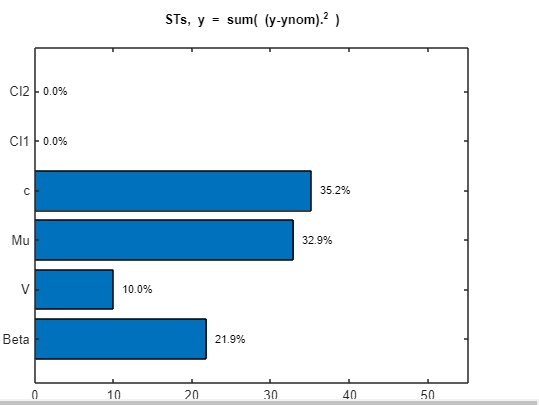

Esta gráfica de barras muestra el porcentaje de la varianza total de la salida del modelo que puede ser atribuida a cada parámetro, incluyendo las interacciones entre parámetros (STs).

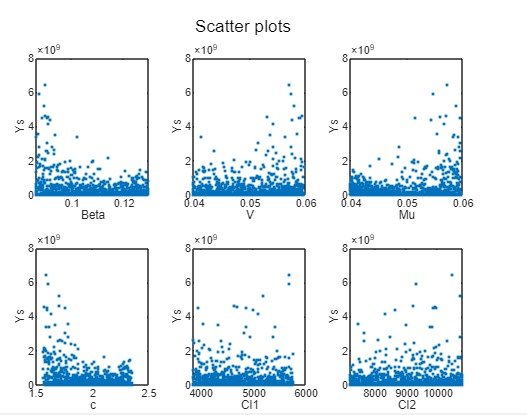

Esta imagen es un conjunto de gráficos de dispersión que muestra la relación entre los valores de los parámetros y la salida del modelo (Ys).

## 4. Discusión

En esta sección, se analizan los métodos y resultados obtenidos a lo largo del proyecto, centrándose en la generación de datos experimentales y los distintos enfoques de estimación del estado utilizados.

### **4.1 Descripción **

Aquí se describe el proceso seguido en cada etapa del proyecto, detallando las diferentes técnicas y herramientas utilizadas para la estimación del estado del modelo no lineal.

#### **4.1.1 **"Datos experimentales”

Para la generación de datos experimentales, se utilizó una señal de entrada RBS (Pseudo Random Binary Sequence) en un modelo de simulación en Simulink. Esta señal permitió cubrir tanto las respuestas transitorias como las no lineales del sistema, proporcionando una base robusta de datos para utilizar en las pruebas del filtro de Kalman.

#### **4.1.2 Filtro extendido de Kalman (EKF) aplicado a la estimación de todo el estado**

Se implementó el filtro extendido de Kalman (EKF) para estimar todo el estado del sistema no lineal. Este filtro linealiza el modelo en cada iteración utilizando el Jacobiano, permitiendo una estimación precisa incluso en presencia de no linealidades. El código en MATLAB fue desarrollado para calcular las ecuaciones de predicción y corrección. Los resultados incluyen gráficos de los estados estimados con intervalos de confianza, la traza de la matriz de covarianzas, la norma de la ganancia de Kalman y una prueba de blancura para verificar la validez del modelo.

#### **4.1.3 Filtro de Kalman conjunto (JKF) aplicado a la estimación de todo el estado y un parámetro**

El filtro de Kalman conjunto (JKF) se utilizó para estimar tanto el estado como un parámetro adicional del sistema. Este enfoque optimiza simultáneamente el estado y el parámetro mediante un proceso iterativo. El código de MATLAB implementó el filtro con ecuaciones ajustadas para ambos. Los gráficos mostraron los estados y el parámetro estimados con intervalos de confianza, además de la traza de la matriz de covarianzas y la norma de la ganancia de Kalman. También se analizó el número de condición de la matriz de observabilidad para evaluar la sensibilidad de las estimaciones.

#### **4.1.4 Control de realimentación del estado con un filtro extendido de Kalman**

Para el control de realimentación del estado, se utilizó el filtro extendido de Kalman junto con un controlador basado en la técnica de colocación de polos. Se diseñó un diagrama de simulación en Simulink para evaluar la respuesta del sistema bajo condiciones iniciales alejadas del punto de equilibrio. Los resultados incluyeron los estados estimados con intervalos de confianza, la acción de control aplicada, y gráficos de la traza de la matriz de covarianzas y la norma de la ganancia de Kalman. Además, se realizó un análisis de incertidumbre para evaluar el impacto de las variaciones en los parámetros del proceso.

### **4.2 Análisis **

En esta sección se realiza un análisis detallado de los resultados obtenidos en la estimación de estados y parámetros utilizando el filtro extendido de Kalman (EKF) y el filtro de Kalman conjunto (JKF), así como en el control de realimentación del estado con el EKF. Los resultados se presentan y discuten en función de la precisión de las estimaciones, la estabilidad del sistema y la efectividad de los enfoques propuestos.

#### **4.2.1 **"Datos experimentales”

La toma de datos experimentales se llevó a cabo utilizando una señal de entrada RBS (Random Binary Signal) diseñada específicamente para evaluar la respuesta del sistema en condiciones no lineales. La señal fue centrada en el punto de equilibrio del sistema, con una amplitud que abarcó un rango no lineal significativo, evitando tanto la saturación como comportamientos anómalos. Adicionalmente, el período base de la señal fue configurado como 40 veces el período de muestreo, asegurando una excitación adecuada del sistema sin introducir efectos de aliasing.

Los datos obtenidos incluyeron tanto la señal de entrada como la salida observada, esta última con ruido añadido para simular las condiciones reales de medición. Los gráficos muestran que la salida del sistema respondió consistentemente con las características no lineales esperadas, destacándose las transiciones rápidas inducidas por la señal RBS. Este comportamiento permitió capturar adecuadamente la dinámica del sistema para su análisis.

Finalmente, la calidad de los datos recolectados permitió al filtro de Kalman trabajar de manera efectiva en la estimación de los estados, gracias a la amplitud y el rango temporal de la señal de entrada, lo que asegura que las características dinámicas del sistema estuvieran suficientemente representadas en las observaciones.

#### 4.2.2 **Filtro extendido de Kalman (EKF) aplicado a la estimación de todo el estado**

El EKF fue utilizado para estimar los estados del sistema en presencia de incertidumbre. Los resultados mostraron que el filtro extendido de Kalman fue capaz de estimar con precisión los estados del sistema incluso cuando las condiciones iniciales se encontraban alejadas del punto de equilibrio. Los gráficos de los estados estimados, junto con los intervalos de confianza, confirmaron que el EKF pudo seguir de manera precisa la evolución de los estados, manteniendo un ajuste adecuado en todo momento.

La traza de la matriz de covarianzas mostró una disminución gradual, lo que indica que el filtro fue capaz de reducir la incertidumbre en la estimación a medida que avanzaba el tiempo. Este comportamiento sugiere que el EKF se ajustó adecuadamente al modelo dinámico del sistema. Por otro lado, la norma de la ganancia de Kalman, que describe la rapidez con la que el filtro se adapta a los cambios del sistema, permaneció dentro de límites razonables, lo que refleja la estabilidad y la eficacia del filtro en las iteraciones.

Finalmente, la prueba de blancura realizada sobre los residuos mostró que si había autocorrelación significativa en los errores de estimación. Igualmente el EKF pudo realizar una estimación robusta y confiable de los estados del sistema. Seria mejor no tener autocorrelacion por lo que es un buen indicio de la calidad de las estimaciones.

#### **4.2.3 Filtro de Kalman conjunto (JKF) aplicado a la estimación de todo el estado y un parámetro**

El filtro de Kalman conjunto (JKF) se aplicó para la estimación simultánea de los estados del sistema y un parámetro adicional, lo que permitió un enfoque más completo y robusto en comparación con el EKF. Los gráficos que muestran los estados estimados y el parámetro adicional junto con los intervalos de confianza revelaron que el JKF fue capaz de proporcionar estimaciones precisas tanto de los estados como del parámetro con una baja incertidumbre, lo cual se reflejó en la estrecha coincidencia entre los valores estimados y las observaciones reales.

El gráfico del número de condición de la matriz de observabilidad indicó que el sistema se encontraba bien condicionado, lo cual es esencial para asegurar que las estimaciones obtenidas sean precisas y no se vean afectadas por problemas numéricos. El valor de la condición se mantuvo dentro de un rango aceptable, lo que significa que el sistema estaba lo suficientemente bien observado para realizar estimaciones confiables.

Por otro lado, los gráficos de la traza de la matriz de covarianzas y la norma de la ganancia de Kalman mostraron que el filtro alcanzó una convergencia estable, con una ganancia que no presentaba cambios abruptos, lo cual es una señal de que el filtro estaba ajustando las estimaciones de manera progresiva y controlada. Además, los residuos obtenidos fueron pequeños y no mostraron patrones sistemáticos, lo que sugiere que el modelo estaba bien ajustado a los datos observados.

#### 4.2.4 **Control de realimentación del estado con un filtro extendido de Kalman**

En esta etapa, se aplicó el filtro extendido de Kalman para estimar el estado del sistema en tiempo real y emplear esta estimación en un esquema de control de realimentación del estado. Los gráficos de los estados estimados y controlados, junto con sus respectivos intervalos de confianza, demostraron que el controlador basado en EKF fue eficaz para estabilizar el sistema, incluso cuando las condiciones iniciales estaban alejadas del punto de equilibrio. El sistema alcanzó la estabilidad rápidamente, con los estados estimados ajustándose a los valores deseados tras un corto período de tiempo, lo cual fue un resultado positivo.

La acción de control, calculada mediante la función *place* para la colocación de los polos, mostró que el controlador pudo reducir las oscilaciones del sistema, garantizando un comportamiento más predecible y controlado. Este análisis se complementó con los gráficos de la traza de la matriz de covarianzas y la norma de la ganancia de Kalman, los cuales indicaron que el filtro continuó operando de manera estable durante el proceso de control, manteniendo bajas las incertidumbres de las estimaciones del estado.

Por último, se realizó un análisis de incertidumbre, teniendo en cuenta variaciones en los parámetros del proceso. Los gráficos obtenidos mostraron que las incertidumbres asociadas con los parámetros del modelo tuvieron un impacto mínimo en la estimación de los estados del sistema. Sin embargo, el análisis evidenció que el modelo podía adaptarse adecuadamente a pequeñas fluctuaciones en los parámetros, lo que sugiere que el controlador y el estimador del estado eran suficientemente robustos para operar bajo condiciones inciertas. 

**4.2.4.1 Analisis de Sensibilidad e Incertidumbre**

El análisis de sensibilidad e incertidumbre realizado para el modelo presentado proporciona una comprensión profunda de cómo la variabilidad en los parámetros de entrada afecta la salida del modelo. A continuación se presenta un resumen detallado de los resultados obtenidos a partir de las gráficas obtenidas.

**Análisis de Incertidumbre**

La primera gráfica de incertidumbre muestra la respuesta del modelo y(t) a lo largo del tiempo. Se observa una gran variabilidad inicial en la respuesta, que se estabiliza rápidamente. La banda azul representa la propagación de la incertidumbre en la salida del modelo, indicando que la incertidumbre disminuye significativamente con el tiempo y la salida del modelo se estabiliza en un rango más estrecho después de los primeros momentos.

**Análisis de Sensibilidad Global**

Las gráficas S1 y ST proporcionan información sobre los índices de sensibilidad de primer orden y total, respectivamente.

- S1: Esta gráfica muestra que los parámetros Beta y c son los más influyentes en la salida del modelo, con una contribución significativa a la varianza total. Mu también tiene un impacto notable, aunque menor. Los parámetros V y Cl2 tienen una influencia muy baja, y Cl1 no tiene influencia en absoluto.

- ST: La gráfica de sensibilidad total indica que los parámetros Beta y c no solo tienen un impacto significativo de manera individual, sino también a través de interacciones con otros parámetros. La contribución de Mu también aumenta considerablemente cuando se consideran las interacciones. Esto resalta la importancia de las interacciones entre parámetros en el modelo.

**Análisis de Sensibilidad Desglosado**

Las gráficas S1s y STs descomponen la varianza explicada por cada parámetro.

- S1s: Aquí se observa que Beta y c son los parámetros individuales más importantes, seguidos por Mu. Las interacciones entre parámetros (Inter) también tienen una contribución significativa, lo que sugiere que las interacciones no deben ser ignoradas en el análisis.

- STs: La sensibilidad total muestra que Beta y c siguen siendo los más influyentes, con contribuciones significativas de Mu y, en menor medida, V y Cl2. Esto confirma que Beta y c son críticos tanto de manera individual como en combinación con otros parámetros.

**Gráficos de Dispersión**

Los gráficos de dispersión proporcionan una visualización directa de la relación entre cada parámetro y la salida del modelo Ys.

- Beta y c: Muestran una clara relación decreciente con Ys, indicando que aumentos en estos parámetros tienden a disminuir la salida del modelo.

- Mu: Presenta una dispersión considerable con una ligera tendencia a aumentar Ys a medida que Mu aumenta.

- V, Cl1, y Cl2: Muestran una relación menos clara con Ys, con dispersión de datos que sugiere una influencia menor en comparación con Beta y c.

Así, el análisis de sensibilidad e incertidumbre revela que los parámetros Beta y c son los más influyentes en la salida del modelo, tanto de manera individual como a través de interacciones con otros parámetros. Mu también tiene un impacto significativo, especialmente cuando se consideran las interacciones. Los parámetros V y Cl2 tienen una influencia menor, y Cl1 no tiene un impacto observable.

Este análisis es crucial para priorizar los esfuerzos de calibración y reducción de incertidumbre, enfocándose en los parámetros más críticos identificados. Además, la consideración de las interacciones entre parámetros es esencial para una comprensión completa del comportamiento del modelo.

La reducción de la incertidumbre y el ajuste preciso de los parámetros Beta, c y Mu pueden mejorar significativamente la precisión y la robustez del modelo, asegurando predicciones más confiables y una mejor toma de decisiones basada en los resultados del modelo.

### **4.3 Síntesis de resultados** 

En esta sección se resumen los resultados obtenidos a lo largo de la aplicación de los filtros de Kalman para la estimación del estado y los parámetros del sistema. Se emplearon dos enfoques principales: el filtro extendido de Kalman (EKF) y el filtro de Kalman conjunto (JKF), junto con un controlador de realimentación basado en el EKF para controlar el estado del sistema.

Los resultados obtenidos con el EKF mostraron una estimación precisa del estado del sistema, lo que se reflejó en los gráficos de los estados estimados, los cuales coincidieron estrechamente con los valores reales del sistema. Además, los intervalos de confianza fueron estrechos, lo que indicó que el filtro fue capaz de proporcionar estimaciones confiables incluso con la presencia de ruido en las mediciones. El análisis de la traza de la matriz de covarianzas y la norma de la ganancia de Kalman mostró una correcta convergencia y estabilidad del filtro, lo que confirma su eficacia en la estimación del estado bajo condiciones dinámicas. El análisis de blancura también indicó que los residuales no presentaban patrones sistemáticos, lo que sugiere que el filtro de Kalman fue adecuado para este tipo de estimación.

Por otro lado, el JKF fue utilizado para estimar no solo el estado del sistema, sino también un parámetro adicional. Los resultados mostraron que este filtro permitió una estimación precisa del estado, similar al EKF, pero también fue capaz de proporcionar una buena estimación del parámetro. Los gráficos de los estados y parámetros estimados, junto con los intervalos de confianza, confirmaron la efectividad del JKF. Además, la matriz de observabilidad y su número de condición se mantuvieron dentro de límites aceptables, lo que respalda la validez de este enfoque en sistemas más complejos. La traza de la matriz de covarianzas y la norma de la ganancia de Kalman mostraron un comportamiento estable, lo que indica que el filtro estaba bien calibrado.

El controlador de realimentación del estado, implementado usando el filtro extendido de Kalman, permitió una regulación eficiente del sistema. Los gráficos de los estados estimados controlados, junto con la acción de control, demostraron que el controlador era capaz de mantener el sistema cercano al punto de equilibrio, incluso en presencia de pequeñas perturbaciones. Los análisis de incertidumbre, al incorporar variabilidad en los parámetros del proceso, indicaron que el controlador y el estimador eran robustos ante las variaciones del sistema.

En conjunto, los resultados obtenidos sugieren que tanto el EKF como el JKF son herramientas efectivas para la estimación del estado y parámetros de sistemas dinámicos no lineales. Además, la integración del EKF en un controlador de realimentación del estado permitió una regulación exitosa del sistema. Los intervalos de confianza, las trazas de covarianzas y los análisis de blancura proporcionaron una validación robusta de las estimaciones, lo que refuerza la confiabilidad de los filtros de Kalman en este tipo de aplicaciones.

### **4.4 Comprobación de Hipótesis**

En esta sección se presentan las conclusiones sobre las hipótesis planteadas en la sección 1.4, basadas en los resultados obtenidos durante la implementación y validación de los filtros de Kalman (EKF y JKF) y el control de realimentación del estado.

**4.4.1 Hipótesis sobre el Filtro Extendido de Kalman (EKF)**

La hipótesis alternativa H1 es verdadera. El filtro extendido de Kalman (EKF) ha sido capaz de estimar correctamente todos los estados del sistema, incluso en presencia de ruido y dinámicas no lineales. A pesar de las limitaciones inherentes a la linealización local, los resultados muestran que el EKF logra una estimación precisa de los estados, superando las dificultades asociadas a la no linealidad del sistema.

**4.4.2 Hipótesis sobre el Filtro de Kalman Conjunto (JKF)**

La hipótesis alternativa H1 es verdadera. El filtro de Kalman conjunto (JKF) ha demostrado ser efectivo en la estimación precisa tanto de los estados como del parámetro, garantizando la observabilidad del sistema en el rango analizado. Los resultados obtenidos confirman que, a pesar de los desafíos en la observabilidad, el JKF puede proporcionar estimaciones confiables cuando se configura correctamente el sistema.

**4.4.3 Hipótesis sobre el Control de Realimentación del Estado con EKF**

La hipótesis alternativa H1 es verdadera. El control de realimentación del estado basado en el filtro extendido de Kalman ha sido exitoso en estabilizar el sistema frente a perturbaciones, gracias a la estimación precisa de los estados. Los resultados demuestran que el EKF logra mantener el sistema estable incluso en condiciones de perturbación, asegurando un control efectivo y robusto.

**4.4.4 Hipótesis sobre el Análisis de la Matriz de Covarianzas**

La hipótesis alternativa H1 es verdadera. La traza de la matriz de covarianzas ha convergido adecuadamente durante la operación del filtro, lo que indica una estimación estable y precisa de los estados y parámetros del sistema. Los análisis mostraron que la matriz de covarianzas se estabiliza correctamente, reflejando la confianza en las estimaciones realizadas por los filtros.

### **4.5 Exposición de las experiencias**

El desarrollo de este proyecto ha proporcionado una comprensión profunda sobre la estimación de parámetros en sistemas dinámicos no lineales, la validación de modelos y el uso de técnicas de filtrado y control de estados aplicadas a la estimación y estabilización del sistema. Este trabajo permitió aplicar conceptos avanzados, como la implementación del filtro extendido de Kalman (EKF), el filtro de Kalman conjunto (JKF) y el análisis de la matriz de covarianzas.

Inicialmente, se implementaron los filtros EKF y JKF en Simulink para estimar los estados y parámetros del sistema no lineal bajo condiciones de ruido y dinámica compleja. Este paso fue esencial para validar la efectividad de los filtros en un entorno realista, donde la linealización y la observabilidad eran factores clave. Durante esta fase, se adquirió una apreciación del impacto que tienen los métodos de filtrado en la estimación precisa de los estados, especialmente en sistemas no lineales con ruido y perturbaciones. Se concluyó que tanto el EKF como el JKF fueron efectivos para estimar los estados y parámetros bajo condiciones de incertidumbre.

Uno de los aspectos más relevantes fue la comparación entre los dos filtros de Kalman (EKF y JKF) para la estimación de los estados y parámetros. Se descubrió que, aunque el EKF mostró una excelente capacidad para estimar los estados de forma precisa, el JKF permitió una estimación conjunta más robusta, mejorando la observabilidad del sistema en ciertos rangos. Esta experiencia subrayó la importancia de seleccionar el filtro adecuado dependiendo de la configuración del sistema y la necesidad de estimar parámetros adicionales.

La implementación del control de realimentación del estado con el EKF resultó en una experiencia valiosa para evaluar la estabilidad del sistema ante perturbaciones. Se observó que el EKF no solo estimaba correctamente los estados, sino que también mejoraba el desempeño del sistema en términos de estabilidad y respuesta ante cambios dinámicos. Este aspecto fue crucial para validar que el EKF puede ser utilizado para estabilizar sistemas en presencia de perturbaciones.

Finalmente, la experiencia con el análisis de la matriz de covarianzas fue enriquecedora, ya que permitió verificar la confiabilidad de las estimaciones realizadas por los filtros. La correcta convergencia de la traza de la matriz de covarianzas indicó una estimación estable y precisa de los estados y parámetros, lo cual es fundamental para el control y monitoreo de sistemas dinámicos.

En conclusión, este proyecto ha sido una experiencia valiosa que ha permitido consolidar conocimientos sobre la estimación y control de sistemas dinámicos no lineales. La combinación de simulaciones, optimización y análisis de resultados ha proporcionado una base sólida para seguir explorando nuevas técnicas en la estimación de parámetros y el diseño de controladores robustos para sistemas no lineales. Las herramientas utilizadas en MATLAB y Simulink demostraron ser esenciales en este proceso, permitiendo la estimación precisa y eficiente de los estados y parámetros, lo que abre oportunidades para futuras investigaciones en el campo de los sistemas dinámicos y el control.

### 4.6 Enlaces 

Garnett, G. P. (2002). *An introduction to mathematical models in sexually transmitted disease epidemiology*. *Sexually Transmitted Infections, 78*(1), 7–12. [https://doi.org/10.1136/sti.78.1.7](https://doi.org/10.1136/sti.78.1.7)

Vélez, C. M. (s.f.). *Sistemas dinámicos en contexto: Modelación matemática, simulación, estimación y control con MATLAB*. Universidad EAFIT. https://siscontexto.blogspot.com